Tehdään ensin mappi:

GW = createGridWorld(10,10,"Standard")

GW =   GridWorld with properties:

          GridSize: [10 10]
      CurrentState: "[1,1]"
            States: [100×1 string]
           Actions: [4×1 string]
                 T: [100×100×4 double]
                 R: [100×100×4 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]



%Create agents
GW.CurrentState = '[2,1]';

GW.TerminalStates = '[2,10]';
GW.ObstacleStates = "[2,5]";

nS = numel(GW.States);
nA = numel(GW.Actions);
GW.R = -1*ones(nS,nS,nA);
GW.R(:,state2idx(GW,GW.TerminalStates),:) = 10;

env = rlMDPEnv(GW)

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


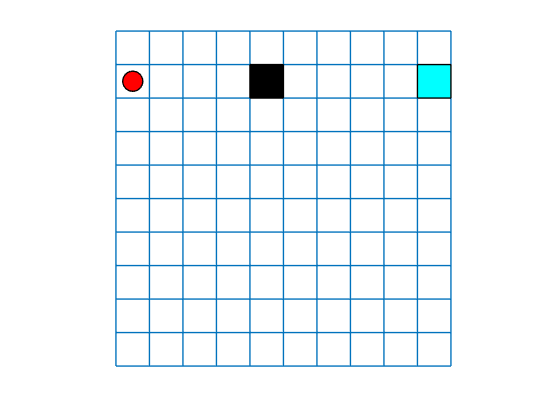


plot(env)

previousRngState = rng(0,"twister");

env = rlPredefinedEnv("BasicGridWorld");

env.ResetFcn = @() 2;

qTable = rlTable(getObservationInfo(env), ...
    getActionInfo(env));

qFcnAppx = rlQValueFunction(qTable, ...
    getObservationInfo(env), ...
    getActionInfo(env));

qAgent = rlQAgent(qFcnAppx);

qAgent.AgentOptions.EpsilonGreedyExploration.Epsilon = .04;
qAgent.AgentOptions.CriticOptimizerOptions.LearnRate = 0.01;

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.MaxEpisodes= 200;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 11;
trainOpts.ScoreAveragingWindowLength = 30;

rng(0,"twister");

doTraining = false;
if doTraining
    % Train the agent.
    qTrainingStats = train(qAgent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load("basicGWQAgent.mat","qAgent")
end

rng(0,"twister");

plot(env)
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;

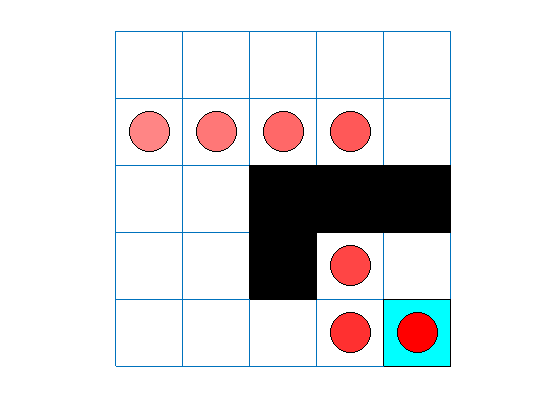

sim(qAgent,env)

sarsaAgent = rlSARSAAgent(qFcnAppx);
sarsaAgent.AgentOptions.EpsilonGreedyExploration.Epsilon = .04;
sarsaAgent.AgentOptions.CriticOptimizerOptions.LearnRate = 0.01;

doTraining = false;
if doTraining
    % Train the agent.
    sarsaTrainingStats = train(sarsaAgent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load("basicGWSarsaAgent.mat","sarsaAgent")
end

rng(0,"twister");

plot(env)
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;

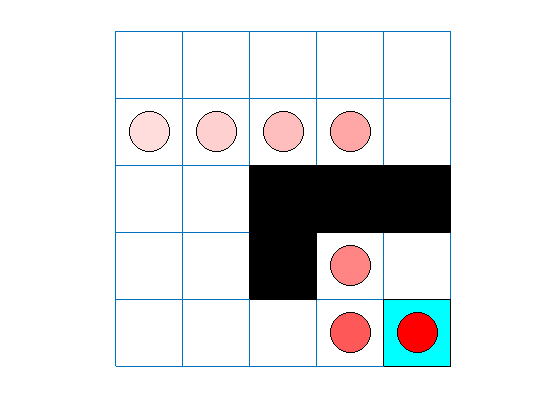

sim(sarsaAgent,env)

rng(previousRngState);

Tehdään prioriteetilla agenttien liikkuminen:

Tehdään PRIMAL-algoritm: